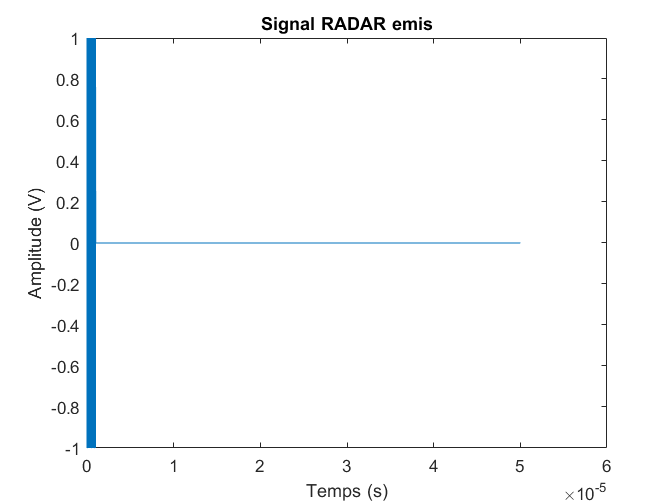

close all;
clear;
clc;

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AVERTISSEMENTS :
%  LES FICHIERS ET DONNEES A TRAITER SONT GROS => LES TEMPS DE CALCUL
% PEUVENT ETRE LONG
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CONSEILS :
% DECOMMENTEZ QUESTION PAR QUESTION ET AU FUR ET A MESURE QU'UNE LIGNE DE
% CODE A TESTER VOUS PARAIT CORRECTE 
% => VERIFIER LE CODE PETIT BOUT PAR PETIT BOUT
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% ----------------------- ----------------------------------------------------------------------------------%
% ----- Questions 1.1 ----------------------------------------------------------------------------------%
% ----------------------------------------------------------------------------------------------------------%
% Decommentez et completez
% 
% ********* Question 1.1.a  ****************************************************************%
EM_Radar_data = load('z_SignalRadarEMIS.txt');
ECHO_Radar1_data = load('z_SignalEchoRadar1.txt');

% Vecteur Temps
Temps = EM_Radar_data(:,1);

% Vecteur Impulsion radar emise
ImpRadarEM= EM_Radar_data(:, 2);

% Vecteur Temps1 => est identique au Vecteur Temps
Temps1 = ECHO_Radar1_data(:,1); % A completer

% Vecteur Echo radar 1
EchoRadar1 = ECHO_Radar1_data(:,2); % A completer


%********* Question 1.1.b  ****************************************************************%
figure(111);
plot(Temps, ImpRadarEM)
title('Signal RADAR emis');
xlabel('Temps (s)');
ylabel('Amplitude (V)');


figure(112);
plot(Temps1, EchoRadar1)
title('Signal RADAR echo');
xlabel('Temps (s)');
ylabel('Amplitude (V)');

figure(113);
hold on
plot(Temps, ImpRadarEM, 'b');
plot(Temps1,EchoRadar1, 'r');
title('Signal RADAR emis et Echo Radar 1');
legend('ImpRadarEM', 'EchoRadar1');
xlabel('Temps (s)');
ylabel('Amplitude (V)');
hold off

%------------------------------------------------------------------------------------------
% La durée des impulsions est de 1us. L'amplitude du signal émis est de 1V, 
% celle du signal recu est de 1/3 V. On remarque que le signal à été atténué 
% lors de sont trajet (allé, collision, retour).
%------------------------------------------------------------------------------------------

%********* Question 1.1.d  ****************************************************************%
% Calcul automatique du retard => 
%------------------------------------------------------------------------------------------
% On trouve le premier point où la tension est différente de 0 sur les deux
% signaux. Et on calcule la différence de temps entre ces deux points.
%------------------------------------------------------------------------------------------

retard = Temps1(find(EchoRadar1, 1)) - Temps(find(ImpRadarEM, 1))

retard = 4.5000e-05


%********* Question 1.1.e  ****************************************************************%
% Calcul distance
%------------------------------------------------------------------------------------------
% L'onde se déplace à la vitesse de la lumière 3e+8 m/s. On peut donc calculer la distance
% connaissant le temps de trajet de l'onde et sa vitesse. 
% /!\ On divise par deux le retard car c'est le temps d'allé retour.
%------------------------------------------------------------------------------------------
vitesse_onde = 3e+8;

distance = vitesse_onde * retard / 2

distance = 6.7500e+03

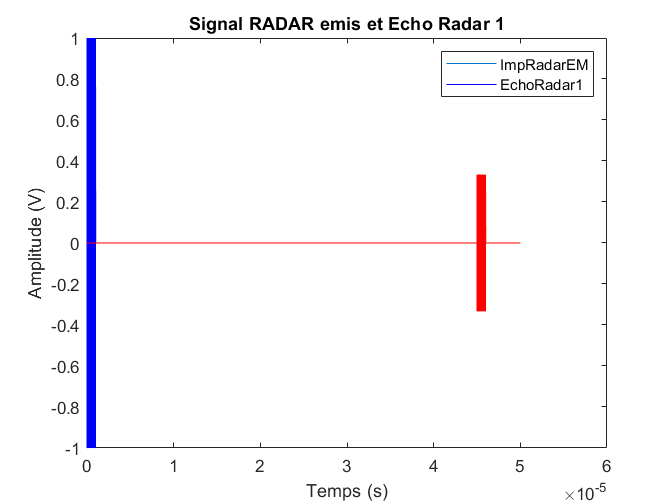


%----------------------- ----------------------------------------------------------------------------------%
%----- Fin Questions 1.1 -------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------% 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%----------------------- ----------------------------------------------------------------------------------%
%----- Questions 1.2 ----------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%
% Decommentez et completez

%********* Question 1.2.a  ****************************************************************%
NbPoint = length(Temps);
Tw = Temps(NbPoint);
Te = Tw / NbPoint;
Fe = 1/Te;

% pas frequentiel
PasFreq = Fe / NbPoint; % A COMPLETER

% Vecteur Frequence pour le tracé dans le domaine Frequentiel
% -Fe/2 -> +Fe/2 (Signal échantillionné à Fe, théorème de Nyquist-Shannon)
Freq = [-(NbPoint-1)/2 : (NbPoint-1)/2] * PasFreq;

%********* Question 1.2.b  ****************************************************************%
%TF du signal Radar Emis
TF_ImpRadarEM = fftshift(fft(ImpRadarEM, NbPoint)); % A completer

% Module et Phase de la TF du signal Radar Emis
Md_TF_ImpRadarEM  = abs(TF_ImpRadarEM) / NbPoint; % A completer
Ph_TF_ImpRadarEM  = (180/pi) * angle(TF_ImpRadarEM); % A completer

% TF du signal EchoRadar1
TF_EchoRadar1 = fftshift(fft(EchoRadar1, NbPoint));% A completer

% Module et Phase de la TF du signal EchoRadar2
Md_TF_EchoRadar1  = abs(TF_EchoRadar1) / NbPoint;; % A completer
Ph_TF_EchoRadar1  = (180/pi) * angle(TF_EchoRadar1);; % A completer

figure(121);

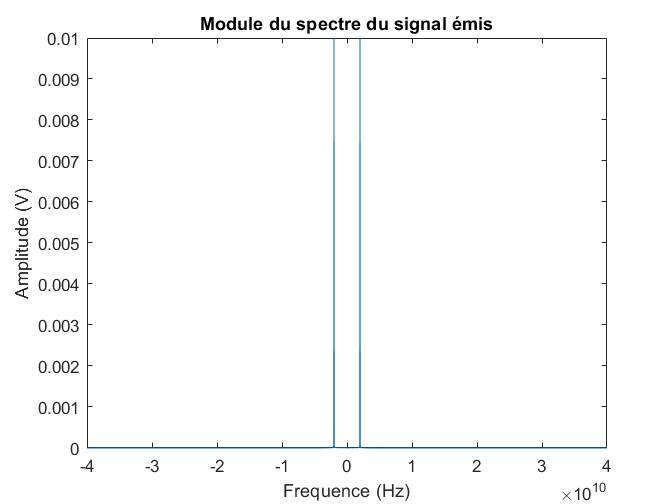

   plot(Freq, Md_TF_ImpRadarEM)
   title('Module du spectre du signal émis');
   xlabel('Frequence (Hz)');
   ylabel('Amplitude (V)');   

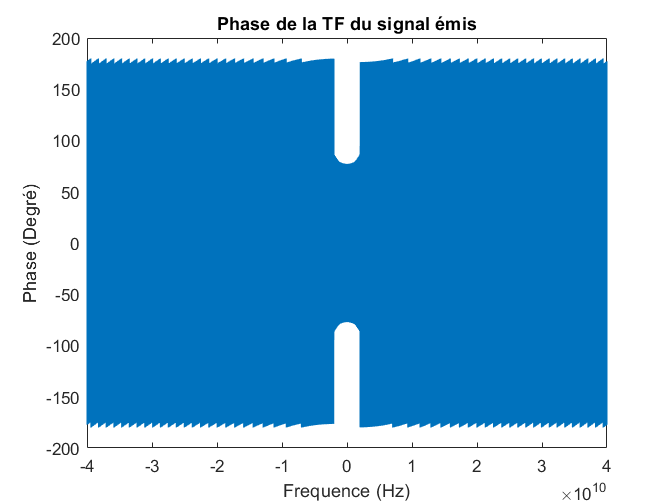


figure(122);
   plot(Freq, Ph_TF_ImpRadarEM)
   title('Phase de la TF du signal émis');
   xlabel('Frequence (Hz)');
   ylabel('Phase (Degré)');

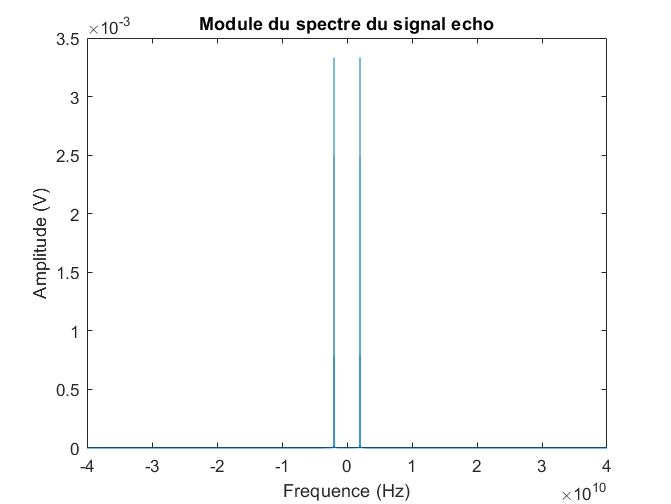


figure(123);
   plot(Freq, Md_TF_EchoRadar1)
   title('Module du spectre du signal echo');
   xlabel('Frequence (Hz)');
   ylabel('Amplitude (V)');

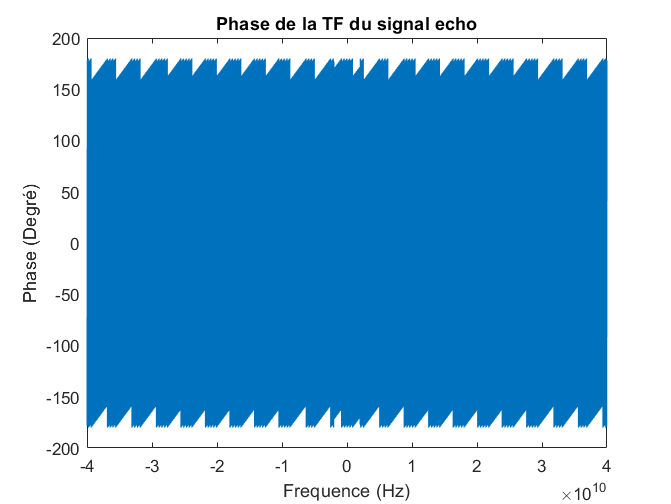


figure(124);
   plot(Freq, Ph_TF_EchoRadar1)
   title('Phase de la TF du signal echo');
   xlabel('Frequence (Hz)');
   ylabel('Phase (Degré)');

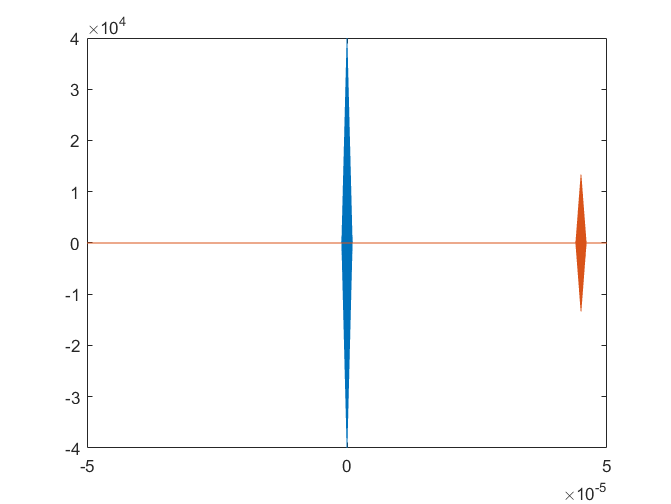


%------------------------------------------------------------------------------------------
% Dans le spectre émis, on observe deux raies à +2MHz et -2MHz d'amplitude
% 9mV. L'amplitude du module est étonament basse par rapport à l'amplitude
% du signale émis. Le signale émis est un sinus de 2MHz enveloppé par un
% signale carrée. Dans le domaine fréquencielle on a donc une raie (pour le
% sinus) convolué avec un sinus cardinal (pour le carré). On l'obesrve bien
% si on zoom sur le pied d'une raie. La puissance du signal est donc
% répartie dans le sinc, ce qui explique l'amplitude max du module reduite.
%------------------------------------------------------------------------------------------

%----------------------- ----------------------------------------------------------------------------------%
%----- Fin Questions 1.2 -------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%----------------------- ----------------------------------------------------------------------------------%
%----- Questions 1.3 ----------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%
% Decommentez et completez

%********* Question 1.3.a  ****************************************************************%
% Correlations
AutoCorr_ImpRadarEM = xcorr(ImpRadarEM, ImpRadarEM); % A completer
InterCorr_ImpRadarEM_EchoRadar1 = xcorr(EchoRadar1, ImpRadarEM);  % A completer

% Nombre de points des correlations
NbPt_AutoCorr = length(AutoCorr_ImpRadarEM); % A completer
NbPt_InterCorr1 = length(InterCorr_ImpRadarEM_EchoRadar1); % A completer

%------------------------------------------------------------------------------------------
% On obtient deux fois plus de points que pour le signale de base.
%------------------------------------------------------------------------------------------

%********* Question 1.3.b  ****************************************************************%
% Affichage des correlations
Temps_AutoCorr   = [-(NbPt_AutoCorr - 1) / 2 : (NbPt_AutoCorr - 1)/2] * Te;

figure(131);
plot(Temps_AutoCorr,   AutoCorr_ImpRadarEM)
hold on
plot(Temps_AutoCorr, InterCorr_ImpRadarEM_EchoRadar1)
hold off

%------------------------------------------------------------------------------------------
% L'autocorrélation nous donne un signale "losange".
% Lorsque la corrélation nous donne un pic max c'est que les deux signaux
% sont identique.
%------------------------------------------------------------------------------------------

%********* Question 1.3.c  ****************************************************************%
% Calcul automatique du retard => AlgoCalculRetard_2
%------------------------------------------------------------------------------------------
% Si on effectue une intercorrélation entre le signale émis et le signale
% recu on retrouve la mçeme forme de signal que pour l'autocorrélation mais
% retardé et avec une amplitude moins importante. 
% L'atténuation de l'amplitude s'explique par l'atténuation que le signale
% a subit lors de la transmission, et le retard nous donne le temps de
% transmission. 
% Pour calculer le retard il nous siffit de caluler la
% differérence de temps entre les deux pics.
%------------------------------------------------------------------------------------------
[ ~, Index] = max(InterCorr_ImpRadarEM_EchoRadar1);
retard_corr = Temps_AutoCorr(Index)

retard_corr = 4.5000e-05


%------------------------------------------------------------------------------------------
% On retrouve bien le même retard que sans corréllation. Pour ce cas nous
% avons aucun intérets d'utiliser l'intercorrélation car les signaux sont
% "parfait", non bruité, ni interféré. Cela nous fait faire des calcules
% plus complexe, et ne nous apporte pas de précision.
%------------------------------------------------------------------------------------------

% ----------------------- ----------------------------------------------------------------------------------%
% ----- Fin Questions 1.3 -------------------------------------------------------------------------------%
% ----------------------------------------------------------------------------------------------------------%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%----------------------- ----------------------------------------------------------------------------------%
%----- Questions 2.1 ----------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%

EM_Radar_data =load('z_SignalRadarEMIS.txt');
ECHO_Radar2_data=load('z_SignalEchoRadar2.txt');

% Vecteur Temps
Temps = EM_Radar_data(:,1);

% Vecteur Impulsion radar emise
ImpRadarEM= EM_Radar_data(:, 2);

% Vecteur Temps2 => est identique au Vecteur Temps
Temps2 = ECHO_Radar2_data(:,1); % A completer

% Vecteur Echo radar 1
EchoRadar2 = ECHO_Radar2_data(:,2); % A completer

%********* Question 2.1.a  ****************************************************************%

figure(211);
plot(Temps, ImpRadarEM)
title('Signal RADAR emis');
xlabel('Temps (s)');
ylabel('Amplitude (V)');

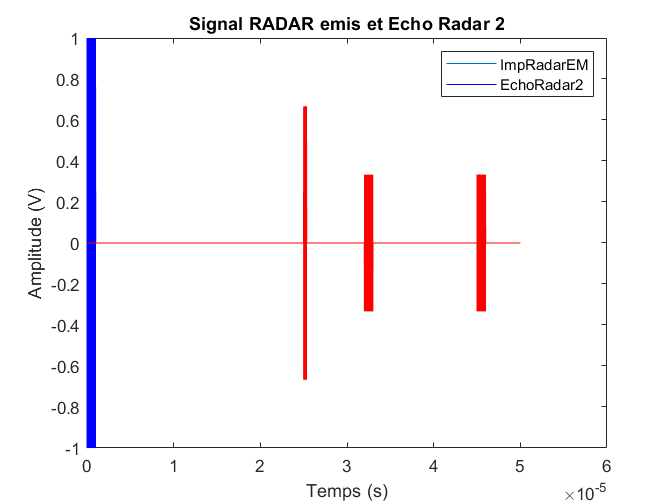


figure(212);
plot(Temps2, EchoRadar2)
title('Signal RADAR echo');
xlabel('Temps (s)');
ylabel('Amplitude (V)');

figure(213);
hold on
plot(Temps, ImpRadarEM, 'b');
plot(Temps2,EchoRadar2, 'r');
title('Signal RADAR emis et Echo Radar 2');
legend('ImpRadarEM', 'EchoRadar2');
xlabel('Temps (s)');
ylabel('Amplitude (V)');
hold off


% Compute frequency axe
NbPoint = length(Temps);
Tw = Temps(NbPoint);
Te = Tw / NbPoint;
Fe = 1/Te;

% pas frequentiel
PasFreq = Fe / NbPoint; % A COMPLETER

%Vecteur Frequence pour le tracé dans le domaine Frequentiel
Freq = [-(NbPoint-1)/2 : (NbPoint-1)/2] * PasFreq;


%********* Question 2.1.d  ****************************************************************%

%TF du signal Radar Emis
TF_ImpRadarEM = fftshift(fft(ImpRadarEM, NbPoint)); % A completer

% Module et Phase de la TF du signal Radar Emis
Md_TF_ImpRadarEM  = abs(TF_ImpRadarEM) / NbPoint; % A completer
Ph_TF_ImpRadarEM  = (180/pi) * angle(TF_ImpRadarEM); % A completer

% TF du signal EchoRadar2
TF_EchoRadar2 = fftshift(fft(EchoRadar2, NbPoint)); % A completer

% Module et Phase de la TF du signal EchoRadar2
Md_TF_EchoRadar2  = abs(TF_EchoRadar2) / NbPoint; % A completer
Ph_TF_EchoRadar2  = (180/pi) * angle(TF_EchoRadar2); % A completer

figure(214);
   plot(Freq, Md_TF_ImpRadarEM)
   title('Module du spectre du signal émis');
   xlabel('Frequence (Hz)');
   ylabel('Amplitude (V)');  


figure(215);
   plot(Freq, Ph_TF_ImpRadarEM)
   title('Phase de la TF du signal émis');
   xlabel('Frequence (Hz)');
   ylabel('Phase (Degré)');

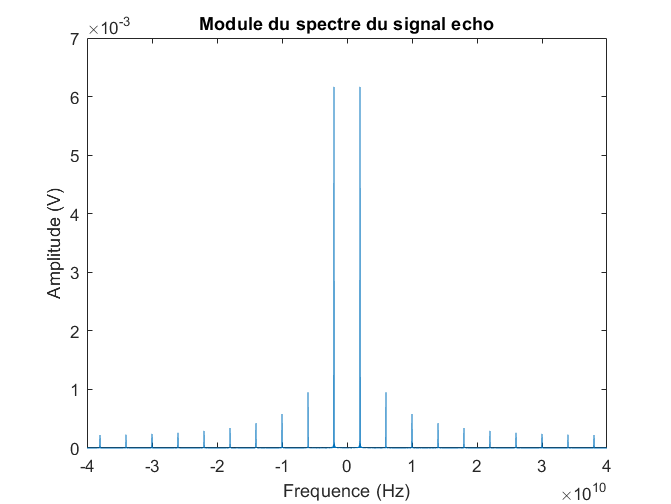


figure(216);
   plot(Freq, Md_TF_EchoRadar2)
   title('Module du spectre du signal echo');
   xlabel('Frequence (Hz)');
   ylabel('Amplitude (V)');

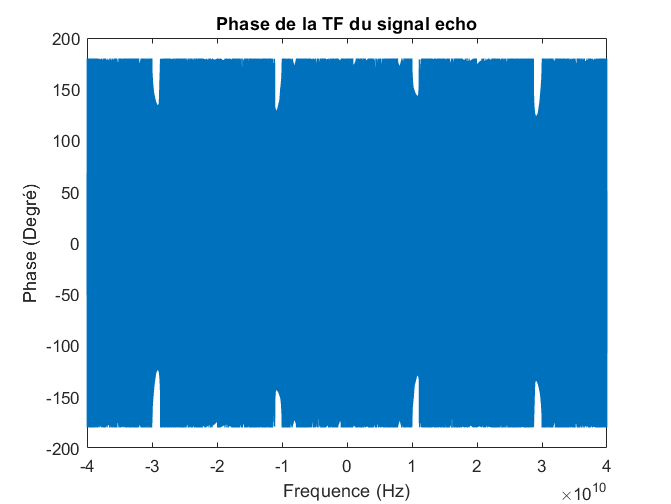


figure(217);
   plot(Freq, Ph_TF_EchoRadar2)
   title('Phase de la TF du signal echo');
   xlabel('Frequence (Hz)');
   ylabel('Phase (Degré)');

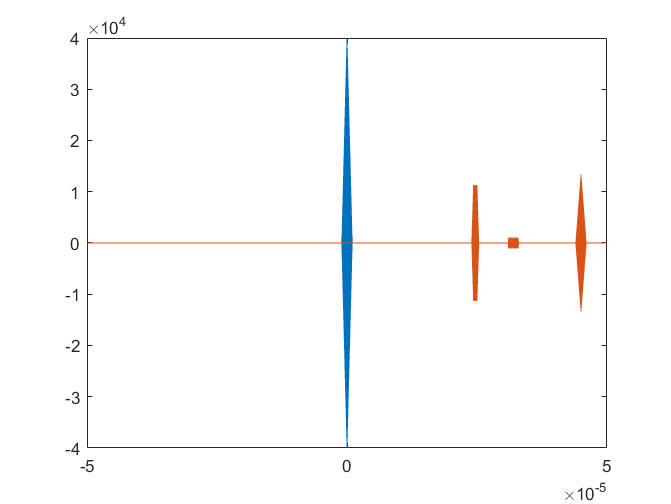


%----------------------- ----------------------------------------------------------------------------------%
%----- Fin Questions 2.1 ------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%----------------------- ----------------------------------------------------------------------------------%
%----- Questions 2.2 ----------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%
% Decommentez et completez

%********* Question 2.2.a  ****************************************************************%
% Correlations
AutoCorr_ImpRadarEM = xcorr(ImpRadarEM, ImpRadarEM); % A completer
InterCorr_ImpRadarEM_EchoRadar2 = xcorr(EchoRadar2, ImpRadarEM); 

% Nonbre de points des correlations
NbPt_AutoCorr = length(AutoCorr_ImpRadarEM); % A completer
NbPt_InterCorr2 = length(InterCorr_ImpRadarEM_EchoRadar2);  

%********* Question 2.2.b  ****************************************************************%
% Affichage des correlation
Temps_AutoCorr   = [-(NbPt_AutoCorr - 1) / 2 : (NbPt_AutoCorr - 1)/2] * Te;

figure(221);
plot(Temps_AutoCorr,   AutoCorr_ImpRadarEM)
hold on
plot(Temps_AutoCorr, InterCorr_ImpRadarEM_EchoRadar2)
hold off


%********* Question 2.2.c  ****************************************************************%
% Calcul automatique du retard => AlgoCalculRetard_1 ou AlgoCalculRetard_2
[ ~, Index] = max(InterCorr_ImpRadarEM_EchoRadar2);
retard_corr = Temps_AutoCorr(Index)

retard_corr = 4.5000e-05

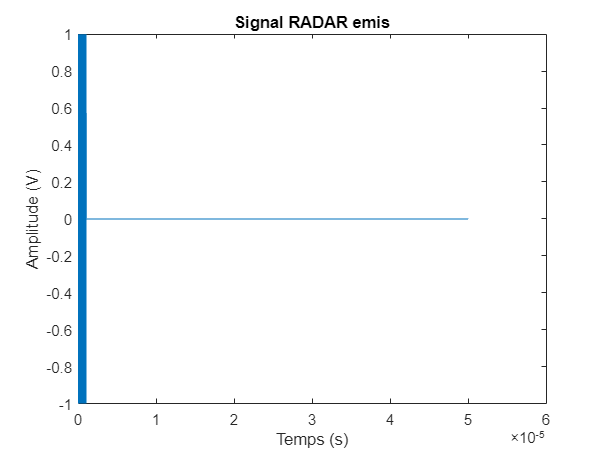


%----------------------- ----------------------------------------------------------------------------------%
%----- Fin Questions 2.2 ------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%----------------------- ----------------------------------------------------------------------------------%
%----- Questions 3.1 ----------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%
EM_Radar_data =load('z_SignalRadarEMIS.txt');
ECHO_Radar3_data=load('z_SignalEchoRadar3.txt');

% Vecteur Temps
Temps = EM_Radar_data(:,1);

% Vecteur Impulsion radar emise
ImpRadarEM= EM_Radar_data(:, 2);

% Vecteur Temps2 => est identique au Vecteur Temps
Temps3 = ECHO_Radar3_data(:,1); % A completer

% Vecteur Echo radar 1
EchoRadar3 = ECHO_Radar3_data(:,2); % A completer

%********* Question 3.1.a  ****************************************************************%

figure(311);
plot(Temps, ImpRadarEM)
title('Signal RADAR emis');
xlabel('Temps (s)');
ylabel('Amplitude (V)');

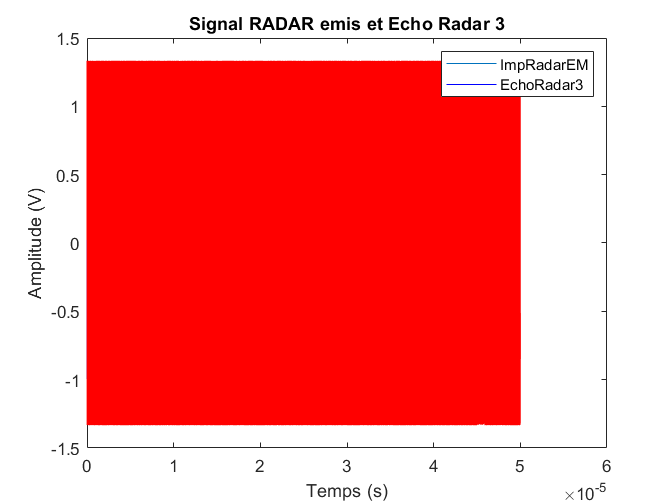


figure(312);
plot(Temps3, EchoRadar3)
title('Signal RADAR echo');
xlabel('Temps (s)');
ylabel('Amplitude (V)');

figure(313);
hold on
plot(Temps, ImpRadarEM, 'b');
plot(Temps3,EchoRadar3, 'r');
title('Signal RADAR emis et Echo Radar 3');
legend('ImpRadarEM', 'EchoRadar3');
xlabel('Temps (s)');
ylabel('Amplitude (V)');
hold off


%------------------------------------------------------------------------------------------
% On observe que le signale recu est complètement noyé dans du bruit. Il
% nous est impossible de le retrouver facilement.
% Les algos utilisé précédement ne peuvent etre utiliser pour retrouver le
% retard.
%------------------------------------------------------------------------------------------

% Compute frequency axe
NbPoint = length(Temps);
Tw = Temps(NbPoint);
Te = Tw / NbPoint;
Fe = 1/Te;

% pas frequentiel
PasFreq = Fe / NbPoint; % A COMPLETER

%Vecteur Frequence pour le tracé dans le domaine Frequentiel
Freq = [-(NbPoint-1)/2 : (NbPoint-1)/2] * PasFreq;

%********* Question 3.1.d  ****************************************************************%

%TF du signal Radar Emis
TF_ImpRadarEM = fftshift(fft(ImpRadarEM, NbPoint)); % A completer

% Module et Phase de la TF du signal Radar Emis
Md_TF_ImpRadarEM  = abs(TF_ImpRadarEM) / NbPoint; % A completer
Ph_TF_ImpRadarEM  = (180/pi) * angle(TF_ImpRadarEM); % A completer

% TF du signal EchoRadar2
TF_EchoRadar3 = fftshift(fft(EchoRadar3, NbPoint)); % A completer

% Module et Phase de la TF du signal EchoRadar2
Md_TF_EchoRadar3  = abs(TF_EchoRadar3) / NbPoint; % A completer
Ph_TF_EchoRadar3  = (180/pi) * angle(TF_EchoRadar3); % A completer

figure(314);
   plot(Freq, Md_TF_ImpRadarEM)
   title('Module du spectre du signal émis');
   xlabel('Frequence (Hz)');
   ylabel('Amplitude (V)');  

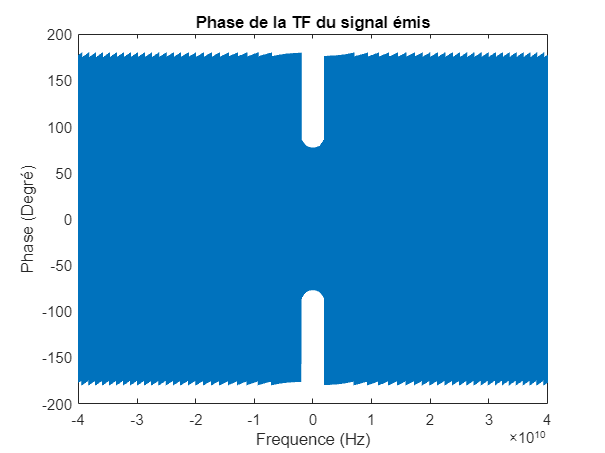


figure(315);
   plot(Freq, Ph_TF_ImpRadarEM)
   title('Phase de la TF du signal émis');
   xlabel('Frequence (Hz)');
   ylabel('Phase (Degré)');

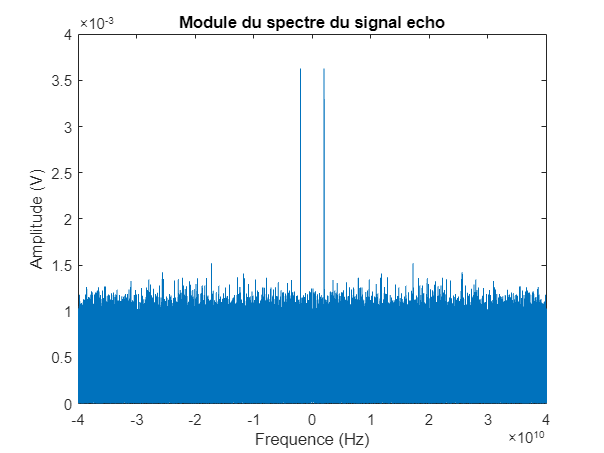


figure(316);
   plot(Freq, Md_TF_EchoRadar3)
   title('Module du spectre du signal echo');
   xlabel('Frequence (Hz)');
   ylabel('Amplitude (V)');

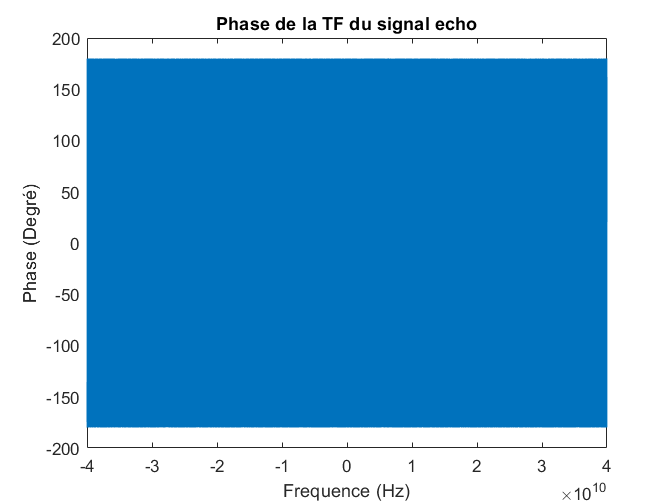


figure(317);
   plot(Freq, Ph_TF_EchoRadar3)
   title('Phase de la TF du signal echo');
   xlabel('Frequence (Hz)');
   ylabel('Phase (Degré)');

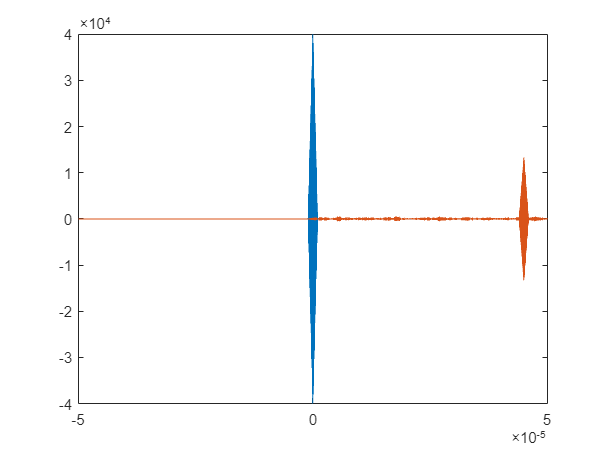


   %------------------------------------------------------------------------------------------
   % On obeserve sur le spectre que le bruit est présent sur toutes les
   % fréquences. Son amplitude est cependant moins importanate que le
   % signale émis. Nous pourrion essayer de filtrer le signale avec un
   % passe bande autour de 2MHz. cela nous donnerai toujours un signale
   % bruité mais nous pourrions peut etre distionguer notre signale émis.
   %------------------------------------------------------------------------------------------

%----------------------- ----------------------------------------------------------------------------------%
%----- Fin Questions 3.1 ------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%----------------------- ----------------------------------------------------------------------------------%
%----- Questions 3.2 ----------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%
% Decommentez et completez

%********* Question 3.2.a  ****************************************************************%
% Correlations
AutoCorr_ImpRadarEM = xcorr(ImpRadarEM, ImpRadarEM); % A completer
InterCorr_ImpRadarEM_EchoRadar3 = xcorr(EchoRadar3, ImpRadarEM); 

% Nonbre de points des correlations
NbPt_AutoCorr = length(AutoCorr_ImpRadarEM); % A completer
NbPt_InterCorr3 = length(InterCorr_ImpRadarEM_EchoRadar3);  

%********* Question 3.2.b  ****************************************************************%
% Affichage des correlation
Temps_AutoCorr   = [-(NbPt_AutoCorr - 1) / 2 : (NbPt_AutoCorr - 1)/2] * Te;

figure(321);
plot(Temps_AutoCorr,   AutoCorr_ImpRadarEM)
hold on
plot(Temps_AutoCorr, InterCorr_ImpRadarEM_EchoRadar3)
hold off

%------------------------------------------------------------------------------------------
% On remarque que l'intercorrélation est super efficace et on parviens a
% retrouver notre signale. On observe juste un légé bruit mais on distingue
% parfaitement le "losange d'intercorrélation" et son pic comme dans les
% signaux précédents. 
%------------------------------------------------------------------------------------------

%********* Question 3.2.c  ****************************************************************%
% Calcul automatique du retard => AlgoCalculRetard_1 ou AlgoCalculRetard_2
[ ~, Index] = max(InterCorr_ImpRadarEM_EchoRadar3);
retard_corr = Temps_AutoCorr(Index)

retard_corr = 4.5000e-05


%------------------------------------------------------------------------------------------
% Le retard retrouvé est identique aux autres. La corrélation est un outil
% très puissant.
%------------------------------------------------------------------------------------------

stop = 1;
%----------------------- ----------------------------------------------------------------------------------%
%----- Fin Questions 3.2 ------------------------------------------------------------------------------%
%----------------------------------------------------------------------------------------------------------%